# IMU Analysis

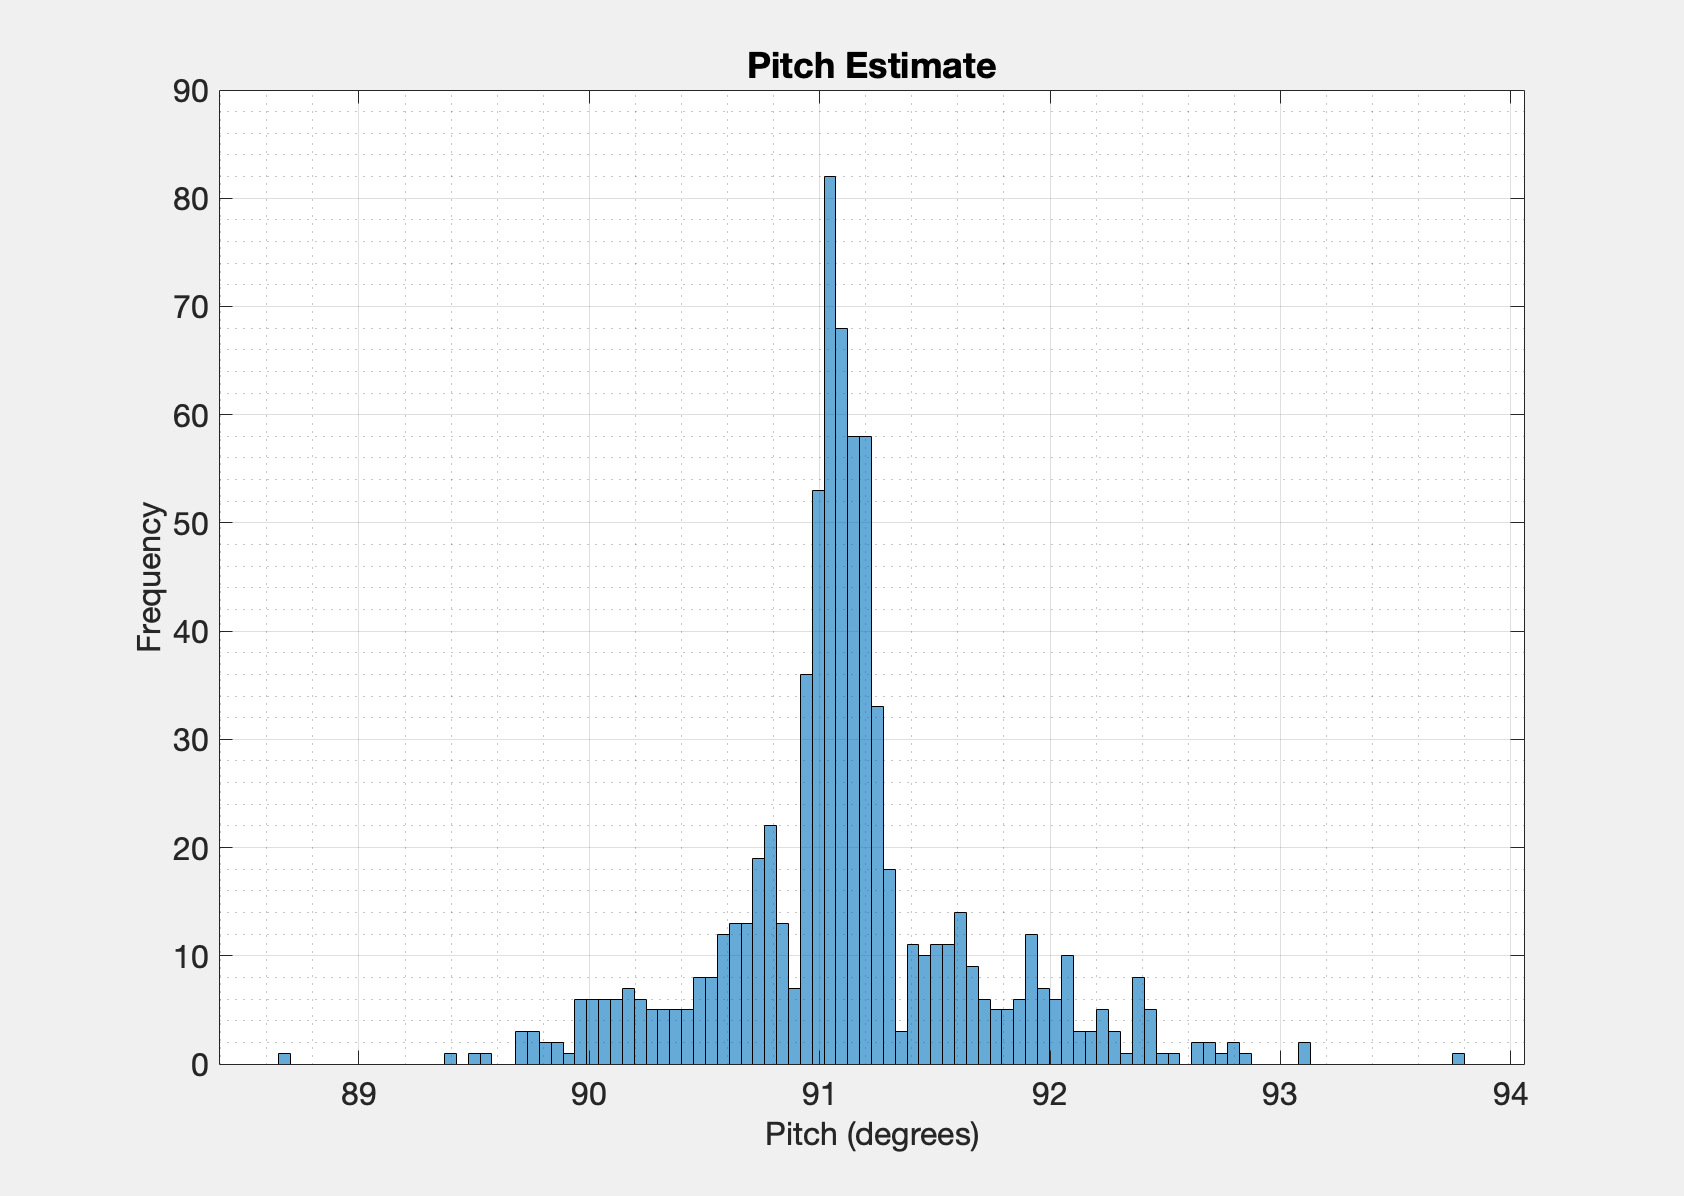

clear
[timestamps, timedelta, data] = parseDataSet("DataSets/MotorIdentification/cl_zn_step.csv");
dt = mean(timedelta)*10^-9;

% Extract data columns
ax = data(:, 3); 
ay = data(:, 4); 
az = data(:, 5);
leftspeed = data(:, 9); 
leftvolt = data(:, 10);
pitch_est = rad2deg(atan2(-ax, az));

fig = figure;
histogram(pitch_est, 100);
ylabel("Frequency");
xlabel("Pitch (degrees)");
fontsize(16, "points");
grid on; grid minor;
title("Pitch Estimate", 'FontSize', 18);
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
exportgraphics(fig, '../Docs/Y3Report/Images/Graphs/noisyPitchEst.pdf')
set(gcf,'Visible', 'on');

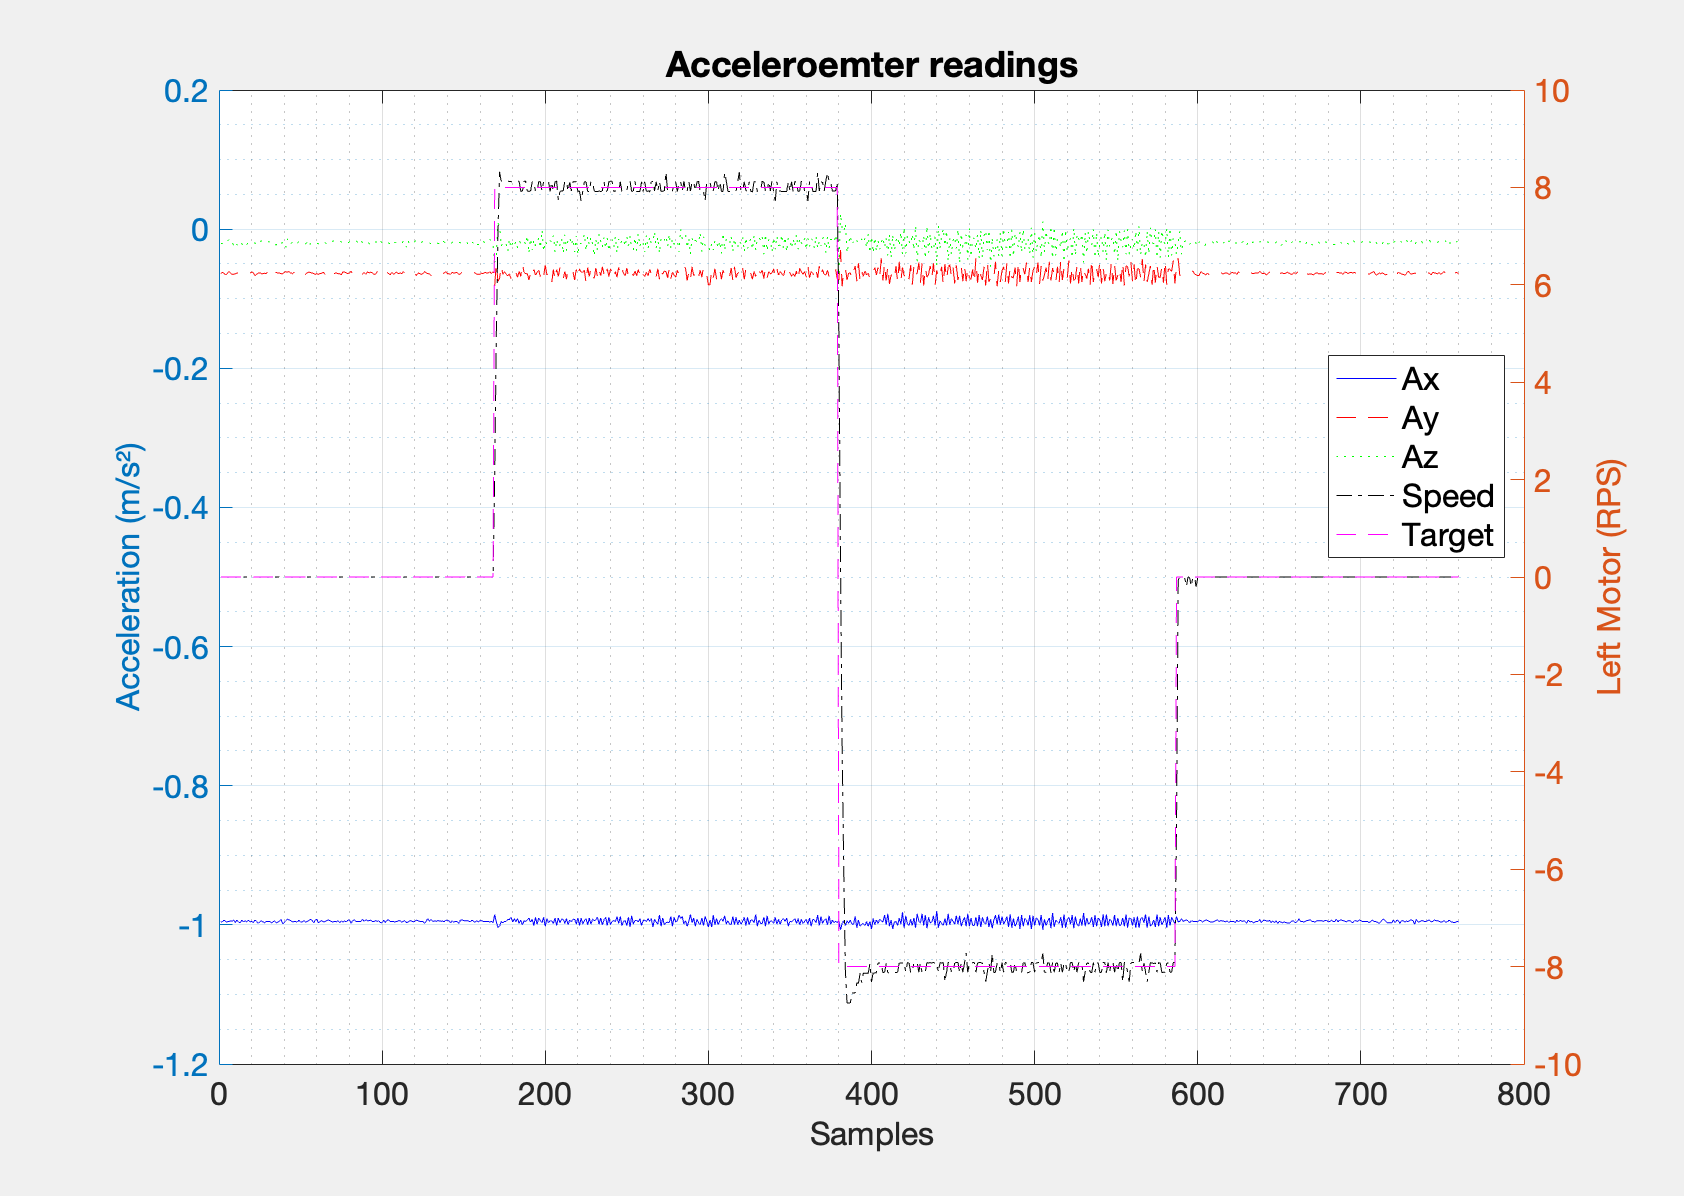


fig = figure;
yyaxis left;
plot(ax, 'b'); hold on; 
plot(ay, 'r'); 
plot(az, 'g'); 
ylabel('Acceleration (m/s²)');
yyaxis right;
plot(leftspeed, 'k-.'); 
plot(leftvolt, 'm--'); 
ylabel('Left Motor (RPS)');
xlabel("Samples");
legend("Ax", "Ay", "Az", "Speed", "Target", 'Location', 'best');
grid on; grid minor;
fontsize(16, "points");
title("Acceleroemter readings",  'FontSize', 18);
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
exportgraphics(fig, '../Docs/Y3Report/Images/Graphs/accelNoiseReadings.pdf')
set(gcf,'Visible', 'on');

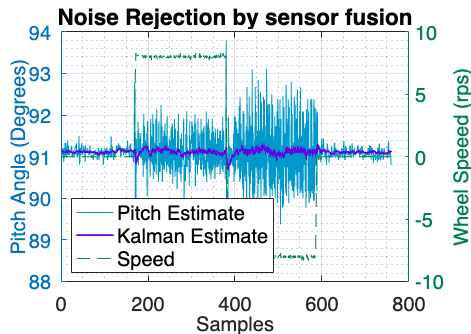


fig = figure;
kal_pitch = data(:,1);
yyaxis left;
plot(pitch_est, 'Color', [0.0, 0.6, 0.8, 0.8],'LineWidth', 0.5);
hold on;  grid on; grid minor; 
plot(kal_pitch,'-', 'Color', [0.40 ,0.0,0.9], 'LineWidth', 1.5); 
ylabel('Pitch Angle (Degrees)')
yyaxis right;
plot(leftspeed, 'k--', 'Color',[0.0, 0.5, 0.3]); 
hold off;
ax = gca;
ax.YColor = [0.0 0.5 0.3];
legend("Pitch Estimate", 'Kalman Estimate', 'Speed', Location='southwest'); 
xlabel("Samples"); 
ylabel('Wheel Speeed (rps)');
fontsize(16, "points");
title('Noise Rejection by sensor fusion', 'FontSize',18); 
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);
exportgraphics(fig, '../Docs/Y3Report/Images/Graphs/sensorFusion.pdf')

set(gcf,'Visible', 'on');
